(3.117)

The frequency response of either a continuous or discrete time system described in state-variable form (see Problem 3.87) may be computed with the use of the MATLAB command freqresp. The syntax is **h = freqresp(sys,w)**, where **sys** is the object containing the state-variable description (see Section 2.14) and **w** is a vector containing the frequencies at which to evaluate the frequency response. Note that **freqresp** applies in general to multiple-input, multiple-output systems, so the output **h** is a multidimentional array. For the class of single-input, single-output systems considered in this text and **N **frequency points in **w, h** is of dimesion 1 by 1 by **N. **The command **squeeze(h)** converts **h **to an **N**-dimensional vector that may be displayed with the **plot** command. Thus, we may obtain the frequency response by using the follwoing commands:

>> h = freqresp(sys,w);

>> hmag = abs(squeeze(h));

>> plot(w,hmag)

>> title('System Magnitude Response');

>> xlabel('Frequency (rads/sec)'); ylabel('Magnitude');

Use MATLAB to plot the magnitude and phase response for the systems with state-variable descriptions given in Problems 3.88 and 3.89.

(Problem 3.88)

(a) $A= \left[\matrix{ -2 & 0 \cr 0 &-1} \right]; b= \left[\matrix{ 0 & \cr 2} \right]; c = [\matrix{1 & 1}];D = [0]$  

(b) $A= \left[\matrix{ 1 & 2 \cr -3 &-4} \right]; b= \left[\matrix{ 1 & \cr 2} \right]; c = [\matrix{0 & 1}];D = [0]$  

(Problem 3.89)

(a) $A= \left[\matrix{ -1/2 & 1 \cr 0 &1/4} \right]; b= \left[\matrix{ 0 & \cr 1} \right]; c = [\matrix{1 & 0}];D = [1]$   

(b) $A= \left[\matrix{ 1/4 & 3/4 \cr 1/4 &-1/4} \right]; b= \left[\matrix{ 1 & \cr 1} \right]; c = [\matrix{0 & 1}];D = [0]$  

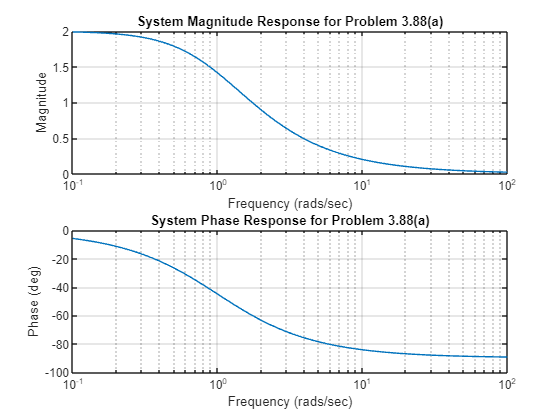

A = [-2, 0; 0, -1];
b = [0; 2];
c = [1, 1];
D = 0;
sys1 = ss(A,b,c,D);

A = [1, 2; -3, -4];
b = [1; 2];
c = [0, 1];
D = 0;
sys2 = ss(A,b,c,D);

A = [-1/2, 1; 0, 1/4];
b = [0; 1];
c = [1, 0];
D = 1;
sys3 = ss(A,b,c,D,-1);

A = [1/4, 3/4; 1/4, -1/4];
b = [1; 1];
c = [0, 1];
D = 0;
sys4 = ss(A,b,c,D,-1);

% w = linspace(0, 100, 500);
% w = logspace(1,5,500);
w = logspace(-1,2,500); 

subplot(2, 1, 1);
h = freqresp(sys1,w);
hmag = abs(squeeze(h));
semilogx(w,hmag)
title('System Magnitude Response for Problem 3.88(a)');
xlabel('Frequency (rads/sec)'); ylabel('Magnitude');
grid on;
subplot(2, 1, 2);
hphase = angle(squeeze(h)) * 180/pi; % convert to degrees
semilogx(w,hphase)
title('System Phase Response for Problem 3.88(a)')
xlabel('Frequency (rads/sec)'); ylabel('Phase (deg)')
grid on;

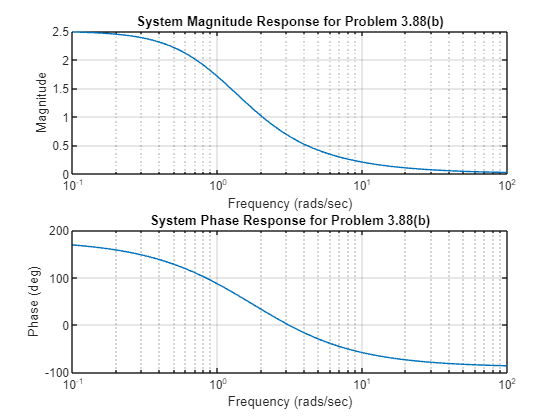


figure
subplot(2, 1, 1);
h = freqresp(sys2,w);
hmag = abs(squeeze(h));
semilogx(w,hmag)
title('System Magnitude Response for Problem 3.88(b)');
xlabel('Frequency (rads/sec)'); ylabel('Magnitude');
grid on;
subplot(2, 1, 2);
hphase = angle(squeeze(h)) * 180/pi; % convert to degrees
semilogx(w,hphase)
title('System Phase Response for Problem 3.88(b)')
xlabel('Frequency (rads/sec)'); ylabel('Phase (deg)')
grid on;

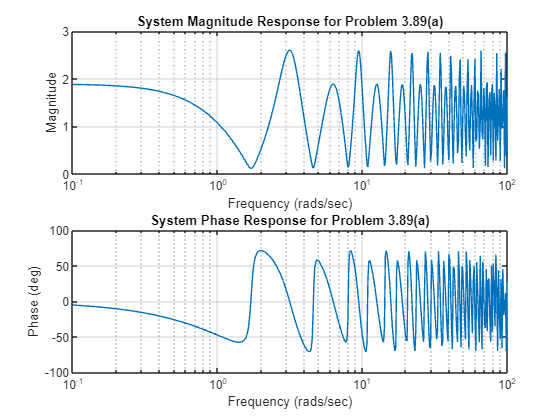


figure
subplot(2, 1, 1);
h = freqresp(sys3,w);
hmag = abs(squeeze(h));
semilogx(w,hmag)
title('System Magnitude Response for Problem 3.89(a)');
xlabel('Frequency (rads/sec)'); ylabel('Magnitude');
grid on;
subplot(2, 1, 2);
hphase = angle(squeeze(h)) * 180/pi; % convert to degrees
semilogx(w,hphase)
title('System Phase Response for Problem 3.89(a)')
xlabel('Frequency (rads/sec)'); ylabel('Phase (deg)')
grid on;

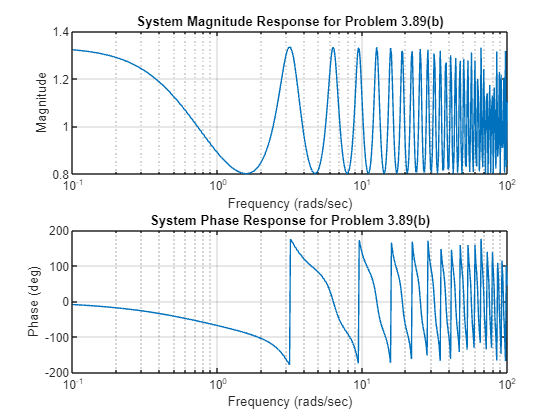


figure
subplot(2, 1, 1);
h = freqresp(sys4,w);
hmag = abs(squeeze(h));
semilogx(w,hmag)
title('System Magnitude Response for Problem 3.89(b)');
xlabel('Frequency (rads/sec)'); ylabel('Magnitude');
grid on;
subplot(2, 1, 2);
hphase = angle(squeeze(h)) * 180/pi; % convert to degrees
semilogx(w,hphase)
title('System Phase Response for Problem 3.89(b)')
xlabel('Frequency (rads/sec)'); ylabel('Phase (deg)')
grid on;